# ENG432 Major Design Project

Samuel Brown 619710

Paramaters

clc; close all; clear all;

% F-16 Dynamics
% Long          % Lat
Xu = -0.0016;   Yb = -27.38;
Xw = 0.0103;    Lb = -28.08;
Zu = -0.1179;   Nb = 5.481;
Zw = -0.3907;   Yp = 0.389;
dMw = 0.0023;   Yr = 0.538;
Mu = 0.0085;    Lp = -1.644;
Mw = 0.0049;    Lr = 0.333;
Mq = -0.500;    Np = -0.081;
Zse = 23.5329;  Nr = -1.504;
Mse = -12.7322; Ysr = 4.588;
Xse = 3.651;    Lsr = 9.591;
Xst = 4.2711;   Lsa = 47.92;
                Nsr = -1.908;
                Nsa = -1.429;
% Vars
v0 = 182;                
m_ref = 0.6;                
m = 9295;
i_x = 12875;
i_y = 75674;
i_z = 85552;                
i_xz = 1331;               
p_den = 0.460;
s_area = 27.871;
b_span = 9.144;
c_chord = 3.45;

% Calc Vars
M = m/(.5*p_den*v0*s_area);
I_x = i_x/(.5*p_den*v0*s_area*b_span);
I_y = i_y/(.5*p_den*v0*s_area*c_chord);
I_z = i_z/(.5*p_den*v0*s_area*b_span);
I_xz = i_xz/(.5*p_den*v0*s_area*b_span);

% dXw, dZw, Xq, Zq, Mst, Zst, Ysa = 0
% [v n τ 𝜉 𝜁 ] => [b se st sa sr]
te = 5*pi/180; We = v0*sin(te); Ue = v0*cos(te); g = 9.81;

% Long Concise Dervivative
xu = Xu/M;
zu = Zu/M;
mu = (Mu/I_y)+(c_chord*dMw*Zu/(v0*I_y*M));
xw = Xw/M;
zw = Zw/M;
mw = (Mw/I_y)+(c_chord*dMw*Zw/(v0*I_y*M));
xq = -We;
zq = Ue;
mq = (c_chord*Mq/I_y)+(Ue*c_chord*dMw/(I_y*v0));
xt = -g*cos(te);
zt = -g*sin(te);
mt = -c_chord*dMw*g*sin(te)/I_y;

xse = v0*Xse/M;
zse = v0*Zse/M;
mse = (v0*Mse/I_y)+(c_chord*dMw*Zse/(I_y*M));
xst = v0*Xst/M;
zst = 0;
mst = 0;

% Lat Concise Derivative
% given beta = y velocity / eqilbrium velocity, 
% the beta data was normalised with the y velocity formula   
yb = Yb/M;
yp = (b_span*Yp+M*We)/M;
yr = (b_span*Yr-M*Ue)/M;
yphi = g*cos(te);
lb = (I_z*Lb+I_xz*Nb)/(I_x*I_z-I_xz^2);
lp = (I_z*Lp+I_xz*Np)/(I_x*I_z-I_xz^2);
lr = (I_z*Lr+I_xz*Nr)/(I_x*I_z-I_xz^2);
lphi = 0;
nb = (I_x*Nb+I_xz*Lb)/(I_x*I_z-I_xz^2);
np = (I_x*Np+I_xz*Lp)/(I_x*I_z-I_xz^2);
nr = (I_x*Nr+I_xz*Lr)/(I_x*I_z-I_xz^2);
nphi = 0;

ysa = 0;
lsa = v0*(I_z*Lsa+I_xz*Nsa)/(I_x*I_z-I_xz^2);
nsa = v0*(I_x*Nsa+I_xz*Lsa)/(I_x*I_z-I_xz^2);
ysr = v0*Ysr/M;
lsr = v0*(I_z*Lsr+I_xz*Lsr)/(I_x*I_z-I_xz^2); 
nsr = v0*(I_x*Nsr+I_xz*Lsr)/(I_x*I_z-I_xz^2); % Error in handout use v0*(I_x not v0*(I_z

% Dim
% [v n τ 𝜉 𝜁 ] => [b se st sa sr]
Xu = -0.0016*.5*p_den*v0*s_area;                Yb = -27.38*.5*p_den*v0*s_area;
Xw = 0.0103*.5*p_den*v0*s_area;                 Lb = -28.08*.5*p_den*v0*s_area*b_span;
Zu = -0.1179*.5*p_den*v0*s_area;                Nb = 5.481*.5*p_den*v0*s_area*b_span;
Zw = -0.3907*.5*p_den*v0*s_area;                Yp = 0.389*.5*p_den*v0*s_area*b_span;
dMw = 0.0023*.5*p_den*s_area*c_chord^2;         Yr = 0.538*.5*p_den*v0*s_area*b_span;
Mu = 0.0085*.5*p_den*v0*s_area*c_chord;         Lp = -1.644*.5*p_den*v0*s_area*b_span^2;
Mw = 0.0049*.5*p_den*v0*s_area*c_chord;         Lr = 0.333*.5*p_den*v0*s_area*b_span^2;
Mq = -0.500*.5*p_den*v0*s_area*c_chord^2;       Np = -0.081*.5*p_den*v0*s_area*b_span^2;
Zse = 23.5329*.5*p_den*v0^2*s_area;             Nr = -1.504*.5*p_den*v0*s_area*b_span^2;
Mse = -12.7322*.5*p_den*v0^2*s_area*c_chord;    Ysr = 4.588*.5*p_den*v0^2*s_area;
Xse = 3.651*.5*p_den*v0^2*s_area;               Lsr = 9.591*.5*p_den*v0^2*s_area*b_span;
Xst = 4.2711;                                   Lsa = 47.92*.5*p_den*v0^2*s_area*b_span;
                                                Nsr = -1.908*.5*p_den*v0^2*s_area*b_span;
                                                Nsa = -1.429*.5*p_den*v0^2*s_area*b_span;

% Dim long
dxu = Xu/m;
dzu = Zu/m;
dmu = (Mu/i_y)+(dMw*Zu/(i_y*m));
dxw = Xw/m;
dzw = Zw/m;
dmw = (Mw/i_y)+(dMw*Zw/(i_y*m));
dxq = -We;
dzq = Ue;
dmq = (Mq/i_y)+(Ue*dMw/(i_y));
dxt = -g*cos(te);
dzt = -g*sin(te);
dmt = -dMw*g*sin(te)/i_y;

dxse = Xse/m;
dzse = Zse/m;
dmse = (Mse/i_y)+(dMw*Zse/(i_y*m));
dxst = Xst/m;
dzst = 0;
dmst = 0;

%Dim lat
dyb = Yb/m;
dyp = (Yp+m*We)/m;
dyr = (Yr-m*Ue)/m;
dyphi = g*cos(te);
dlb = (i_z*Lb+i_xz*Nb)/(i_x*i_z-i_xz^2);
dlp = (i_z*Lp+i_xz*Np)/(i_x*i_z-i_xz^2);
dlr = (i_z*Lr+i_xz*Nr)/(i_x*i_z-i_xz^2);
dlphi = 0;
dnb = (i_x*Nb+i_xz*Lb)/(i_x*i_z-i_xz^2);
dnp = (i_x*Np+i_xz*Lp)/(i_x*i_z-i_xz^2);
dnr = (i_x*Nr+i_xz*Lr)/(i_x*i_z-i_xz^2);
dnphi = 0;

dysa = 0;
dlsa = (i_z*Lsa+i_xz*Nsa)/(i_x*i_z-i_xz^2);
dnsa = (i_x*Nsa+i_xz*Lsa)/(i_x*i_z-i_xz^2);
dysr = Ysr/m;
dlsr = (i_z*Lsr+i_xz*Lsr)/(i_x*i_z-i_xz^2); 
dnsr = (i_x*Nsr+i_xz*Lsr)/(i_x*i_z-i_xz^2);

% Long
x1 = {'u' 'w' 'q' 'theta'};
a1 = [xu xw xq xt; zu zw zq zt; mu mw mq mt; 0 0 1 0];

b1 = [xse xst; zse zst; mse mst; 0 0];
c1 = [0 1 0 0; 0 0 1 0];
u1 = {'se' 'st'};
y1 = {'z velocity' 'pitch rate'};

c12 = [1 0 0 0; 0 0 0 1];
y12 = {'x velocity' 'pitch angle'};

% Lat
x2 = {'beta' 'p' 'r' 'phi'};
a2 = [yb yp yr yphi; lb lp lr lphi; nb np nr nphi; 0 1 0 0];

b2 = [ysa ysr; lsa lsr; nsa nsr; 0 0];
c2 = [0 0 0 1; 0 0 1 0];
u2 = {'sa' 'sr'};
y2 = {'bank angle' 'yaw rate'};

c22 = [1 0 0 0; 0 1 0 0];
y22 = {'sideslip angle' 'roll rate'};

% Dim
% Long
da1 = [dxu dxw dxq dxt; dzu dzw dzq dzt; dmu dmw dmq dmt; 0 0 1 0];
db1 = [dxse dxst; dzse dzst; dmse dmst; 0 0];

% Lat
da2 = [dyb dyp dyr dyphi; dlb dlp dlr dlphi; dnb dnp dnr dnphi; 0 1 0 0];
db2 = [dysa dysr; dlsa dlsr; dnsa dnsr; 0 0]; 



Question 2) Open loop step response

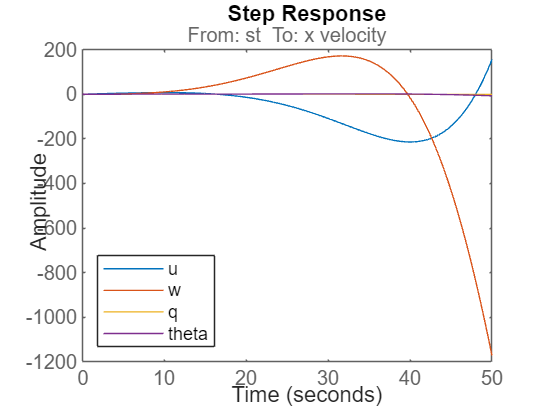

st = 0.01;       %A) (1% Thrust)
se = 0.0174533;  %B)  rad (1deg increase in Elevator positon)
sa = 0.0174533;  %C)  rad (1deg increase in Aileron position)
sr = 0.0174533;  %D)  rad (1deg increase in Rudder position)

sys_mimo11 = ss(a1,b1,c1,0,'statename',x1,...
'inputname',u1,...
'outputname',y1);

sys_mimo21 = ss(a2,b2,c2,0,'statename',x2,...
'inputname',u2,...
'outputname',y2);

sys_mimo12 = ss(a1,b1,c12,0,'statename',x1,...
'inputname',u1,...
'outputname',y12);

sys_mimo22 = ss(a2,b2,c22,0,'statename',x2,...
'inputname',u2,...
'outputname',y22);

stSysW = sys_mimo11(1,2);
seSysW = sys_mimo11(1,1);
saSysR = sys_mimo21(1,1);
srSysR = sys_mimo21(1,2);
stSysQ = sys_mimo11(2,2);
seSysQ = sys_mimo11(2,1);
saSysPhi = sys_mimo21(2,1);
srSysPhi = sys_mimo21(2,2);

stSysU = sys_mimo12(1,2);
seSysU = sys_mimo12(1,1);
saSysB = sys_mimo22(1,1);
srSysB = sys_mimo22(1,2);
stSysTheta = sys_mimo12(2,2);
seSysTheta = sys_mimo12(2,1);
saSysP = sys_mimo22(2,1);
srSysP = sys_mimo22(2,2);

optSe = RespConfig;
optSe.Amplitude = se;

optSa = RespConfig;
optSa.Amplitude = sa;

optSt = RespConfig;
optSt.Amplitude = st;

optSr = RespConfig;
optSr.Amplitude = sr;

t1 = 0:0.05:50;
t2 = 0:0.05:50;

%Long sys
figure; grid on; hold on;
step(stSysU,t1, optSt)
step(stSysW,t1, optSt)
step(stSysQ,t1, optSt)
step(stSysTheta,t1, optSt)
legend(x1,Location="southwest"); hold off;

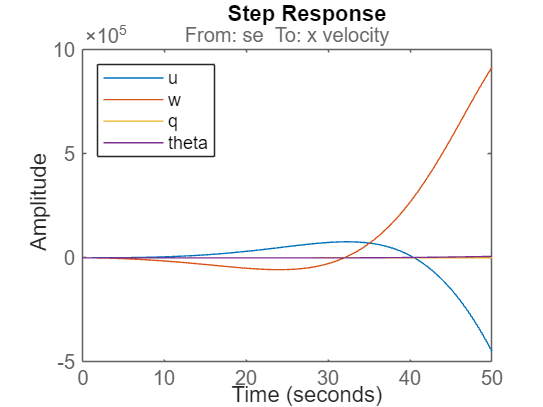


figure; hold on;
step(seSysU,t1, optSe)
step(seSysW,t1, optSe)
step(seSysQ,t1, optSe)
step(seSysTheta,t1, optSe)
legend(x1,Location="northwest"); hold off;

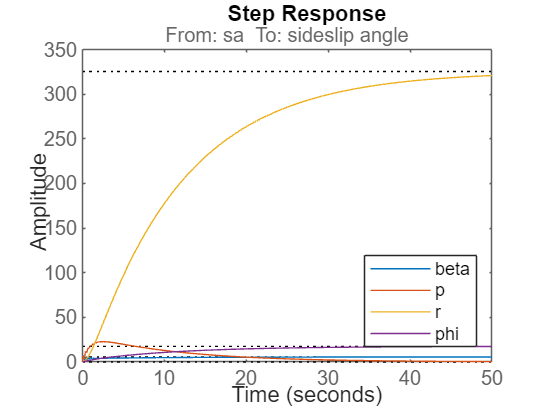


%Lat sys
figure; hold on;
step(saSysB,t2, optSa)
step(saSysP,t2, optSa)
step(saSysR,t2, optSa)
step(saSysPhi,t2, optSa)
legend(x2,Location="southeast"); hold off;

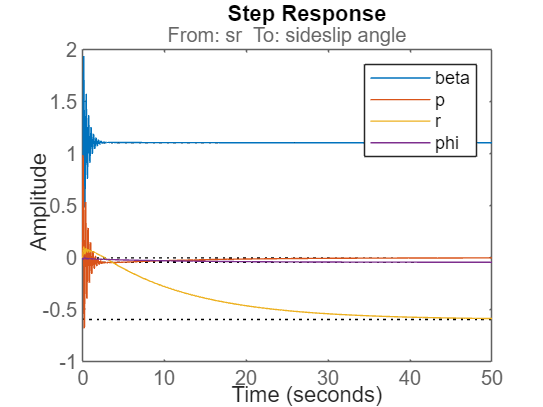


figure; hold on;
step(srSysB,t2, optSr)
step(srSysP,t2, optSr)
step(srSysR,t2, optSr)
step(srSysPhi,t2, optSr)
legend(x2,Location="northeast"); hold off;

Question 3) Controllability and Observability

co1 = ctrb(a1,b1);
unCo1 = length(a1) - rank(co1)

unCo1 = 0


co2 = ctrb(a2,b2);
unCo2 = length(a2) - rank(co2)

unCo2 = 0


b = zeros(4,2);
unCoA = zeros(4,2);
unCoB = zeros(4,2);

for k = 1:2
    for j = 1:4
        b = zeros(4,2);
        b(j,k) = 1;

        coA = ctrb(a1,b);
        unCoA(j,k) = length(a1)-rank(coA);
        coB = ctrb(a2,b);
        unCoB(j,k) = length(a2)-rank(coB);

    end
end

unCoA

unCoA =      0     0
     0     0
     0     0
     0     0


unCoB

unCoB =      0     0
     0     0
     0     0
     0     0



c = zeros(2,4);
unOb1 = zeros(2,4);
unOb2 = zeros(2,4);

for k = 1:4
    for j = 1:2
        c = zeros(2,4);
        c(j,k) = 1;

        ob1 = obsv(a1,c);
        unOb1(j,k) = length(a1)-rank(ob1);
        ob2 = obsv(a2,c);
        unOb2(j,k) = length(a2)-rank(ob2);

    end
end

unOb1

unOb1 =      0     0     0     0
     0     0     0     0


unOb2

unOb2 =      0     0     0     0
     0     0     0     0


Question 4) Major Minor Loop Design

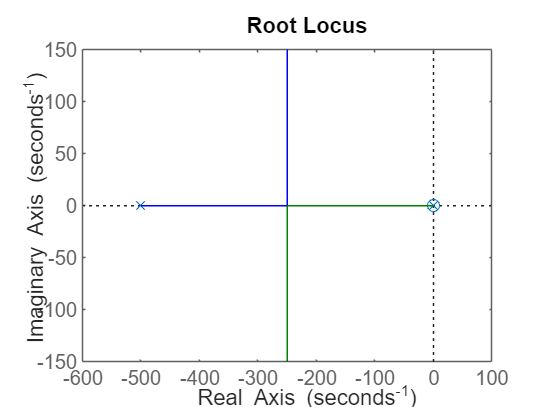

s = tf('s');

t = .002;
b = 1/t;
delay = b / (s + b);

pl = tf(ss(a1, b1, [0 0 1 0], 0));
pl = pl(1);

Gmin = pl*delay;

K2 = -6;
GminL = K2 * Gmin;
rlocus(GminL)

TminL = feedback(GminL, 1);
Tmin = minreal(zpk(TminL), 2e-3);
[ppS, zzS] = pzmap(Tmin)

ppS = 1.0e+02 *

  -2.5005 + 5.5433i
  -2.5005 - 5.5433i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i


zzS = 1.0e-03 *

   -0.2907
    0.0000


[WnS, zetaS, pS] = damp(Tmin);

wnS = WnS(end);
zS = zetaS(end);

zP = .04;
wnP = wnS/10;

sP = zP*wnP 

sP = 2.4325

wdP = wnP*sqrt(1-zP^2)

wdP = 60.7628

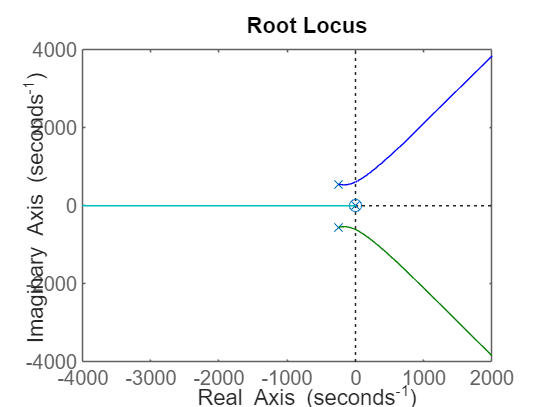


K1 = 6;
Gmaj = K1 * Tmin / s;
rlocus(Gmaj)

TmajL = feedback(Gmaj, 1);
Tmaj = minreal(zpk(TmajL), 1e-3);
[ppP, zzP] = pzmap(Tmaj)

ppP = 1.0e+02 *

  -0.0605 + 0.0000i
  -0.0000 + 0.0000i
  -2.4702 + 5.5299i
  -2.4702 - 5.5299i


zzP = -2.9069e-04

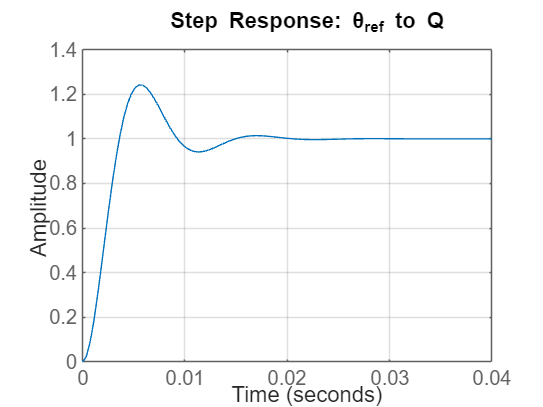

[WnP, zetaP, pP] = damp(Tmaj);

figure;
step(Tmin, .04);
title('Step Response: θ_{ref} to Q');
grid on;

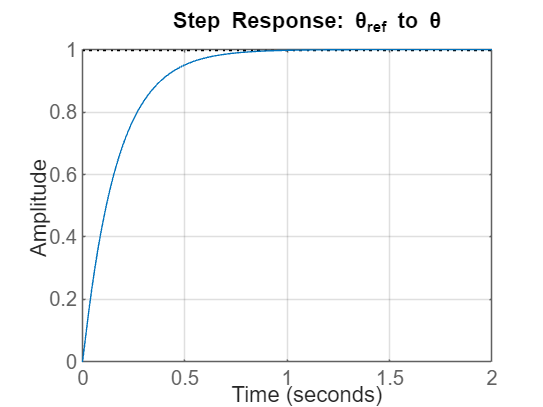


figure;
step(Tmaj, 2);
title('Step Response: θ_{ref} to θ');
grid on;


gain4 = dcgain(Tmaj)

gain4 = 0.9971

Question 5) LQR Regulator

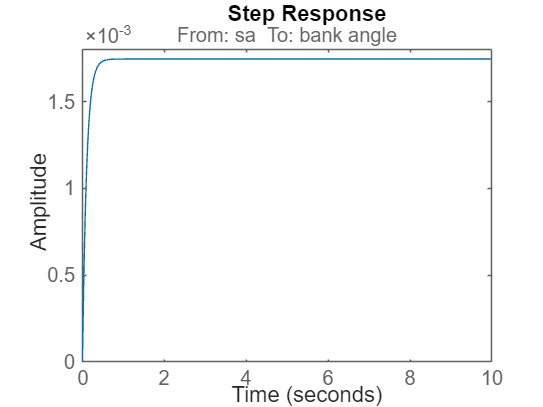

c15 = [0 0 0 1]; % phi

% isolate aileron
B_sa = b2(:,1);

Q = diag([0, 1, 0, 1e2]);
R = 1;

K = lqr(a2, B_sa, Q, R);

A5lqr = a2 - B_sa*K;

y5 = {'bank angle'};
u5 = {'sa'};

sys_siso5 = ss(A5lqr,B_sa,c15,0,'statename',x2,...
'inputname',u5,...
'outputname',y5);

opt5 = RespConfig;
opt5.Amplitude = sr;

t5 = 0:0.01:10;

step(sys_siso5, t5, opt5)

Question 6) Controller Pole Placement

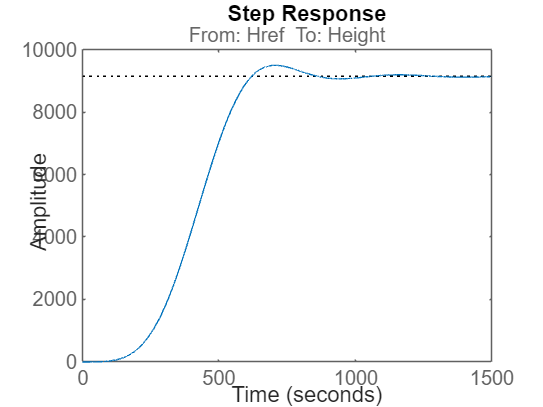

syms s;

% Define reference values
Href = 0.3048 * 30000;  % 30,000 ft in meters
Uref = 182;             % Speed in m/s

% Augment the system to include height h, where dh/dt = -w
A_a = [0, 0, -1, 0, 0; zeros(4,1), a1];
B_a = [zeros(1,2); b1];
C_a = [1, 0, 0, 0, 0; 0, 1, 0, 0, 0]; % Controlled outputs: h and u

ctrb_a = rank(ctrb(A_a,B_a));

% Split into siso systems
C_u = [1 0 0 0];
C_h = C_a(1,:);
B_u = b1(:,2);
B_h = B_a(:,1);

ctrb_u = rank(ctrb(a1,B_u));
ctrb_h = rank(ctrb(A_a,B_h));

% Servomechanism 
A_sm_h = [A_a zeros(5,1); -C_h 0];
B_sm_h = [B_h; 0];
C_sm_h = [C_h 0];

ctrb_sm_h = rank(ctrb(A_sm_h,B_sm_h));

A_sm_u = [a1 zeros(4,1); -C_u 0];
B_sm_u = [B_u; 0];
C_sm_u = [C_u 0];

ctrb_sm_u = rank(ctrb(A_sm_u,B_sm_u));

% Define desired closed-loop poles for controller
wn = .01;
ITAE5 = s^5 + 2.8*wn*s^4 + 5*wn^2*s^3 + 5.5*wn^3*s^2 + 3.4*wn^4*s + wn^5;
ITAE6 = s^6 + 3.25*wn*s^5 + 6.6*wn^2*s^4 + 8.6*wn^3*s^3 + 7.45*wn^4*s^2 + 3.95*wn^5*s + wn^6;
EigCoH = vpasolve(ITAE6, s);
EigCoU = vpasolve(ITAE5, s);

k_h = place(double(A_sm_h), double(B_sm_h), double(EigCoH));
K_h = k_h(1:5);
Ke_h = -k_h(6);

k_u = place(double(A_sm_u), double(B_sm_u), double(EigCoU));
K_u = k_u(1:4);
Ke_u = -k_u(5);

a_h = [A_a - B_h*K_h, B_h*Ke_h; -C_h 0];
b_h = [zeros(5,1); 1];
c_h = [C_h 0];

a_u = [a1 - B_u*K_u, B_u*Ke_u; -C_u 0];
b_u = [zeros(4,1); 1];
c_u = [C_u 0];


y6 = {'Height'};
x6 = {'h' 'u' 'w' 'q' 'theta' 'N'};
r6 = {'Href'};

y62 = {'X velocity'};
x62 = {'u' 'w' 'q' 'theta' 'N'};
r62 = {'Uref'};


sys_siso6_h = ss(a_h,b_h,c_h,0,'statename',x6,...
'inputname',r6,...
'outputname',y6);

sys_siso6_u = ss(a_u,b_u,c_u,0,'statename',x62,...
'inputname',r62,...
'outputname',y62);

opt = RespConfig;
opt.Amplitude = Href;

t = 0:0.1:1500;

step(sys_siso6_h,t,opt)

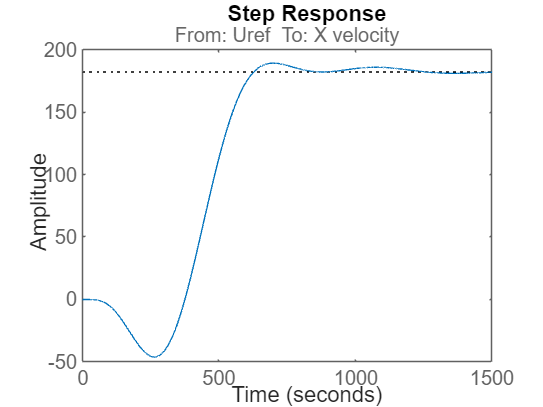


optU = RespConfig;
optU.Amplitude = Uref;

t = 0:0.1:1500;
step(sys_siso6_u,t,optU)

Question 7) Model Perdictive Control